# Anualidades

## Pago anticipado


$$M=C*\left(1+i\right)\left\lbrack \frac{\left({\left(1+i\right)}^n -1\right)}{i}\right\rbrack$$


Un trabajador realiza un ahorro programado durante 4 años para lo cual autorizó a la empresa un descuento mensual de su salario de 3M de pesos, cuánto logrará acumular en dicho período de tiempo si le reconocen una tasa de interés compuesto del 24% anual de forma anticipada con capitalización mensual y al finalizar el segundo año agrega una cuota por 20M.

C = 3e6;
in = 0.24/12;
n = 4*12;
M1 = C * (1 + in) * ((((1 + in)^n) - 1)/in);
n2 = n/2;
M2 = 20e6 * (1 + in)^n2;
MT = M1 + M2;

Capitalización indica interés compuesto y anticipado indica por anualidades.


$$M=3M\left(1+0\ldotp 02\right)\left\lbrack \frac{\left({\left(1+0\ldotp 02\right)}^{48} -1\right)}{0\ldotp 02}\right\rbrack$$



$$\begin{array}{l}
\textrm{M1}=242M\\
\textrm{M2}={C\left(1+i\right)}^n \\
\textrm{M2}=20{M\left(1+0\ldotp 02\right)}^{24} \\
\textrm{M2}=32\ldotp 168\ldotp 745\\
\textrm{MT}=\textrm{M1}+\textrm{M2}\\
\textrm{MT}=274\ldotp 168\ldotp 745
\end{array}$$


Para un viaje se compromete ahorrar en un fondo de inversión la suma de 2M anuales por 8 años, con cuánto dinero dispondrá al final de la inversión si el fondo le paga los primeros 3 años el 9% anual, y los otros 5 años el 10% anual.

clear
clc

C = 2e6;
in = 0.09;
n = 3;
M1 = C * (1 + in) * ((((1 + in)^n) - 1)/in);

n = 5;
in = 0.1;
M2 = C * (1 + in) * ((((1 + in)^n) - 1)/in);

in = 0.1;
M3 = M1 * (1 + in)^n;

MT = M2 + M3;

## Amortización

Valor base que fijo se paga o abona directamente a capital en una deuda


$$T=\frac{V}{n}$$


T : Amortización

V : Valor o monto a financiar

n : Cuota periódica

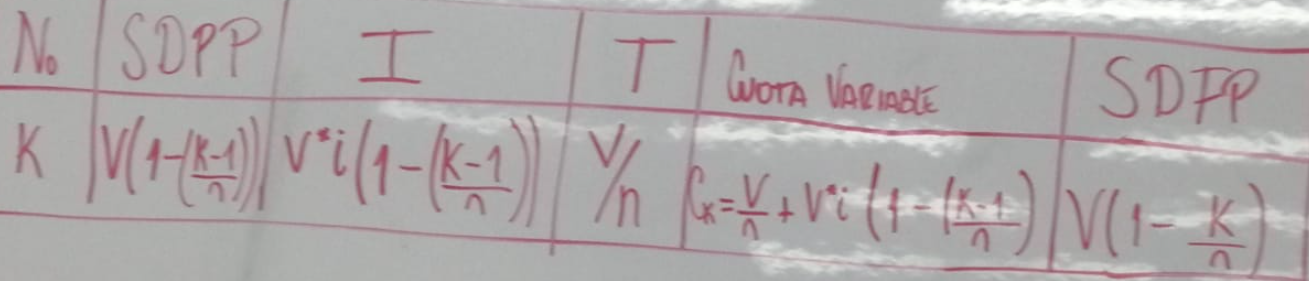

K : Número de cuota

I : Interés

T : Amortización

$C_K$ : Cuota variable

SDPP : Saldo de deuda principio del período

SDFP : Saldo de deuda final del período

Ejemplo:

Una empresa requiere 50M y solicita un préstamo a un banco por dicho monto a un plazo de 5 meses y una tasa de interés del 24% anual por el sistema de cuota vairable, determinar el valor de la amortización y el valor de las 5 cuotas


$$n_{o\;} :$$


SDPP=50M

I=1M

T=10M

Cv=11M

SDFP=40M

La cuota variable será el valor de la amoritzación más los intereses

clear
clc
i = 0.24/12;
V = 50e6;
n = 5;
T = V/n;

for k = 1:n

    SDPP(k) = V * (1 - ((k - 1)/n));
    I(k) = V * i * (1 - ((k - 1)/n));
    Cv(k) = T + I(k);
    SDFP(k) = V * (1 - (k/n));

end

I =      1.0000e+006


I =      1.0000e+006   800.0000e+003


I =      1.0000e+006   800.0000e+003   600.0000e+003


I =      1.0000e+006   800.0000e+003   600.0000e+003   400.0000e+003


I =      1.0000e+006   800.0000e+003   600.0000e+003   400.0000e+003   200.0000e+003


Un préstamo de 100M que usted solicita a un banco se otorga por 5 años a una tasa del 10% anual, realice un plan de pago de cuotas semestrales durante dicho período, cuál es el valor de la cuota 7 y cuál es el valor del SDFP en esa cuota.

Solo se determina la cuota 7:


$$\begin{array}{l}
k=1\\
\textrm{SDPP}=100M\left(1-\left(\frac{7-1}{10}\right)\right)=40M\\
I=100M*0\ldotp 05\left(1-\left(\frac{7-1}{10}\right)\right)=2M\\
T=\frac{100M}{10}\\
\textrm{Cv}=10M+2M\\
\textrm{SDFP}=100M\left(1-\frac{7}{10}\right)=30M
\end{array}$$


clear
clc
i = 0.10/2;
V = 100e6;
n = 10;
T = V/n;

for k=1:n

    SDPP(k) = V * (1 - ((k - 1)/n));
    I(k) = V * i * (1 - ((k - 1)/n));
    Cv(k) = T + I(k);
    SDFP(k) = V * (1 - (k/n));
    
end

Siempre que se pueda buscar abonar a capital.

# Finanzas personales

Hacer siempre presupuesto de gastos, el ahorro debe ser mínimo del 20% mientras se está con papás aún, tras salir lo ideal es que tal ahorro sea de mínimo el 10%, además siempre buscar invertir, es decir destinar el ahorro para capitalizar.

El manejo de la deuda debe ser con la búsqueda de eliminar rápidamente esa deuda, entre más tiempo más interés se paga, por ello siempre aportar a capital.

Entender los ciclos económicos, siempre va a haber un auge y le va a seguir una recesión tendiendo a una depresión.

Los momentos de crisis también se deben tomar como una oportunidad pues son momentos propicios para lograr una inversión.

El patrimonio siempre debe ir en aumento, esto permite tener mayor tipo de inversión.


$$\textrm{PIB}=C+I+G+\left(X-M\right)$$


$C:$ consumo

$I:$ inversión

 $G:$ gasto

$X-M:$ diferencia entre exportaciones e importaciones

## Liquidez

Capital de trabajo: $\textrm{Activo}\;\textrm{total}-\textrm{Pasivo}\;\textrm{total}=\$$

Indice de liquidez: $\frac{\textrm{Activo}}{\textrm{Pasivo}}=\textrm{veces}$

Razón corriente: $\frac{\textrm{Activo}\;\textrm{Corriente}}{\textrm{Pasivo}\;\textrm{Corriente}}=\textrm{veces}$

Nivel de endeudamiento: $\frac{\textrm{Pasivo}\;\textrm{total}}{\textrm{Activo}\;\textrm{total}}=%$

Siempre salir primero de la deuda con mayor tasa de interés.

En el balance se analizan las pérdidas y ganancias de las empresas, siempre buscando cerrar sus años vencidos en positivo para este concepto

## TCO o CTO

CTO: Costo Total de Operación

## Capex y Opex

Capex: Todo gasto de capital 

Opex: Todo gasto de operación

No solo es mirar en tener el activo, es mirar lo que genera mayor rentabilidad